# Plant

%Make sure to open the HybridSystemPerformance project.  This will set up
%paths correctly and clear the workspace.

plantPath = strcat(commonPath,'\Plant Model\');
latestPlant = latestTimeParse(plantPath,'plant');
load(latestPlant)
clear plantPath latestPlant

# Globals

t_final = 10;
delta_t = 0.005;
t = 0:delta_t:t_final;

# Input Signals

inputPath = strcat(commonPath,'\Performance Input Signals\');
latestSlow = latestTimeParse(inputPath,'performanceInputsSlow');
latestFast = latestTimeParse(inputPath,'performanceInputsFast');
latestPureSin = latestTimeParse(inputPath,'pureSin');
load(latestSlow)
load(latestFast)
load(latestPureSin)
clear inputPath latestSlow latestFast latestPureSin

# Toggles

togSweeps = 0;
sweepMode = 0; %0 for slow input frequencies, 1 for high input frequencies
togSweepPlots = 0;
togWeightSurface = 0;
togOptimumSinglePoint = 0;
togTrackingPhasePlane = 1;

# Sweeps

if togSweeps == 1
    Kp = .5:.5:15;
    Ki = .5:.5:15;
    td = 0.04:0.04:0.04;
    numinners = size(Kp,2)*size(Ki,2);
    
    chirprmses = zeros(numinners,3,size(td,2));
    sosrmses = zeros(numinners,3,size(td,2));
    strisetime = zeros(numinners,3,size(td,2));
    stsettlingtime = zeros(numinners,3,size(td,2));
    stovershoot = zeros(numinners,3,size(td,2));
    
    for i = 1:size(td,2)
        tic
        iter = 1;
        for j = 1:size(Kp,2)
            tic
            for k = 1:size(Ki,2)
                %Controller TF
                C_tf = tf([Kp(j) Ki(k)],[1 0]);
                
                %Delay (Pade approximation)
                [nump,denp]=padeWrap(td);
                d_tf = tf(nump,denp);
                
                %Closed Loop Transfer Function
                num = C_tf*G_plant;
                den = (1 + num*d_tf);
                cl_tf = num/den;
                
                %Stability
                s = isstablemod(cl_tf);
                if s == 1
                    stepopt=stepDataOptions('StepAmplitude',scale);
                    %step
                    st = stepinfo(step(cl_tf,stepopt));
                    
                    %Performance Metrics
                    if st.RiseTime < 0
                       strisetime(iter,:,i) = [Kp(j) Ki(k) 0];
                    else
                        strisetime(iter,:,i) = [Kp(j) Ki(k) st.RiseTime];
                    end
                    
                    if st.SettlingTime < 0
                        stsettlingtime(iter,:,i) = [Kp(j) Ki(k) 0]; 
                    else
                        stsettlingtime(iter,:,i) = [Kp(j) Ki(k) st.SettlingTime];
                    end
    
                    if st.Overshoot < 0
                        stovershoot(iter,:,i) = [Kp(j) Ki(k) 0]; 
                    else
                        stovershoot(iter,:,i) = [Kp(j) Ki(k) st.Overshoot];
                    end
    
                    
                    %lsim
                    if sweepMode == 0
                        chirpsim = lsim(cl_tf,chirps_slow,t);
                        sossim = lsim(cl_tf,sos_slow,t);
                        chirprmse = sqrt(mean((chirps_slow-chirpsim').^2));
                        sosrmse = sqrt(mean((sos_slow-sossim').^2));
                    else
                        chirpsim = lsim(cl_tf,chirps_fast,t);
                        sossim = lsim(cl_tf,sos_fast,t);   
                        chirprmse = sqrt(mean((chirps_fast-chirpsim').^2));
                        sosrmse = sqrt(mean((sos_fast-sossim').^2));
                    end

                    %Errors
                    chirprmses(iter,:,i) = [Kp(j) Ki(k) chirprmse];
                    sosrmses(iter,:,i) = [Kp(j) Ki(k) sosrmse];
                    iter = iter + 1;
                    
                else
    
                end
                
            end
            toc
        end
        toc
    end
    
    if sweepMode == 0
        basepath = strcat(commonPath,'\Smooth Performance Results');
        savePath = genFileName(basepath,'performanceSweep');
        save(savePath,'Kp','Ki','td','chirprmses','sosrmses','strisetime','stsettlingtime','stovershoot','sweepMode','chirps_slow','sos_slow','chirps_fast','sos_fast','scale')      
    else
        basepath = strcat(commonPath,'\Smooth Performance Results');
        savePath = genFileName(basepath,'performanceSweep');
        save(savePath,'Kp','Ki','td','chirprmses','sosrmses','strisetime','stsettlingtime','stovershoot','sweepMode','chirps_slow','sos_slow','chirps_fast','sos_fast','scale')              
    end
end

# Sweep Plots

if togSweepPlots == 1
    subn = 1;
    subp = 1;
    
    figure
    for i =  1:size(td,2)
        performanceSurfacePlot(chirprmses,subn,subp,i,Kp,Ki,td)
    end
    sgtitle('RMSE Performance for Chirp input with increasing delay')
    
    figure
    for i =  1:size(td,2)
        performanceSurfacePlot(sosrmses,subn,subp,i,Kp,Ki,td)
    end
    sgtitle('RMSE Performance for SoS input with increasing delay')
    
    figure
    for i =  1:size(td,2)
        performanceSurfacePlot(strisetime,subn,subp,i,Kp,Ki,td)
    end
    sgtitle('Rise time of step response with increasing delay')
    
    figure
    for i =  1:size(td,2)
        performanceSurfacePlot(stsettlingtime,subn,subp,i,Kp,Ki,td)
    end
    sgtitle('Settling time of step response with increasing delay')
    
    figure
    for i =  1:size(td,2)
        performanceSurfacePlot(stovershoot,subn,subp,i,Kp,Ki,td)
    end
    sgtitle('Overshoot of step response with increasing delay')    
end

# Weighting and Composite Surface

if togWeightSurface == 1
    weights = [0.2 0.2 0.2 0.2 0.2]'; %Chirp SSE, SoS SSE, Rise, Settling, Overshoot
    ind04 = 1;
    
    chirperror04 = zerostrip(chirprmses(:,:,ind04));
    normchirprmses = normalize(chirperror04(:,3),'range');
    
    soserror04 = zerostrip(sosrmses(:,:,ind04));
    normsosrmses = normalize(soserror04(:,3),'range');
    
    risetime04 = zerostrip(strisetime(:,:,ind04));
    normrisetime = normalize(risetime04(:,3),'range');
    
    settlingtime04 = zerostrip(stsettlingtime(:,:,ind04));
    normsettlingtime = normalize(settlingtime04(:,3),'range');
    
    overshoot04 = zerostrip(stovershoot(:,:,ind04));
    normovershoot = normalize(overshoot04(:,3),'range');
    
    norms = [normchirprmses normsosrmses normrisetime normsettlingtime normovershoot];
    composite = norms*weights;
    
    sfcomposite = fit([overshoot04(:,1),overshoot04(:,2)],composite,'cubicinterp');
    
    figure
    plot(sfcomposite)
    xlabel('K_P')
    ylabel('K_I')
    zlabel('Composite score')
    title('t_d = 0.04')
    
    [minimum,index] = min(composite);
    minKp = overshoot04(index,1)
    minKi = overshoot04(index,2)
    
    if togOptimumSinglePoint == 1
        C_tf = tf([minKp minKi],[1 0]);
        
        %Delay (Pade approximation)
        td =.04;
        [nump,denp]=padeWrap(td);
        d_tf = tf(nump,denp);
        
        %Closed Loop Transfer Function
        num = C_tf*G_plant;
        den = (1 + num*d_tf);
        cl_tf = num/den;
        
        %Sims
        if sweepMode == 0
            optchirpsim = lsim(cl_tf,chirps_slow,t);
            optsossim = lsim(cl_tf,sos_slow,t);
            figure
            plot(t,chirps_slow,t,optchirpsim)
            figure
            plot(t,sos_slow,t,optsossim)
        else
            optchirpsim = lsim(cl_tf,chirps_fast,t);
            optsossim = lsim(cl_tf,sos_fast,t);     
            figure
            plot(t,chirps_slow,t,optchirpsim)
            figure
            plot(t,sos_slow,t,optsossim)            
        end

        figure
        step(cl_tf);
        figure
        margin(cl_tf)
        figure('Position', [100, 100, 1024, 1200]);
        subplot(2,1,1)
        h = nyquistplot(oltf);
        p = getoptions(h);
        p.XLim = {[-3, 0.5]};
        p.YLim = {[-1.5, 1.5]};
        setoptions(h,p);
        subplot(2,1,2)
        pzmap(cl_tf);
    end
end

# Tracking Error, pure sin (FRF)

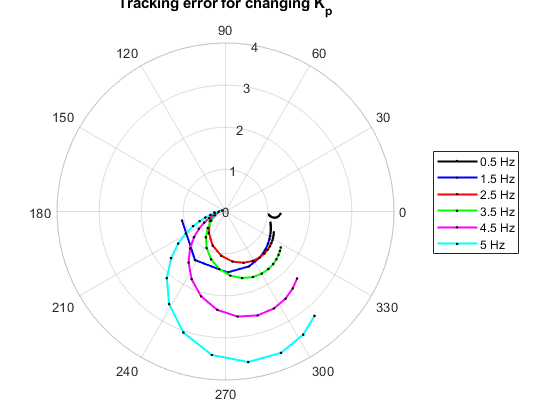

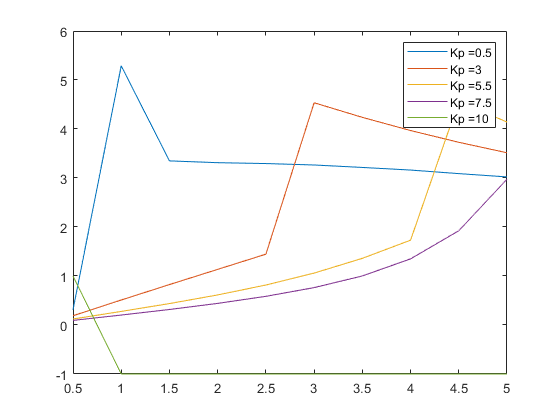

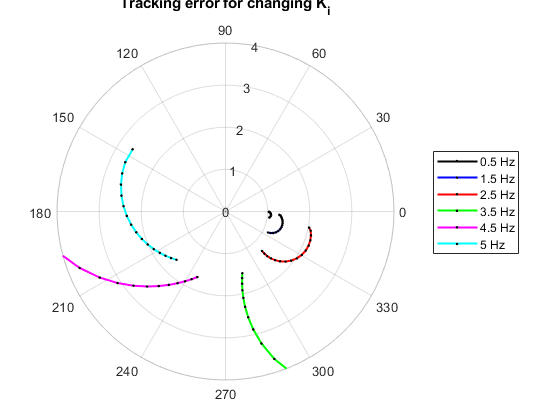

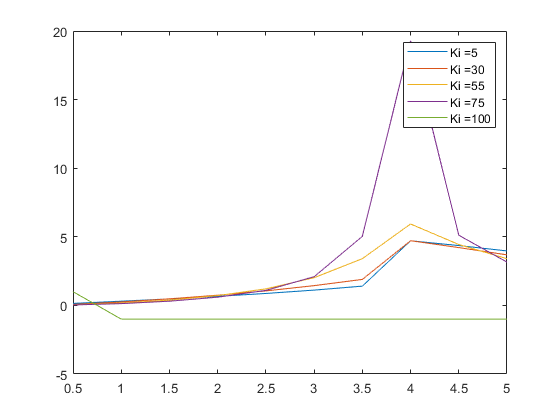

if togTrackingPhasePlane == 1
    lineColors = [{'k'} {'b'} {'r'} {'g'} {'m'} {'c'}];
    selectedFreqIndices = [1 3 5 7 9 10];
    
    %Proportional Gain Sweep
    Kp = 0.5:0.5:10;
    Ki = 10;
    selectedArrayIndices = round(linspace(1,length(Kp),5));
    
    %Delay (Pade approximation)
    td =.04;

    [tmagsP,tphasesP] = trackingErrorPlot(G_plant,Kp,Ki,td,0,pureSinTime,pureSin,sinfreqs,lineColors,...
    selectedFreqIndices,selectedArrayIndices);

    %Integral Gain Sweep
    Kp = 5;
    Ki = 5:5:100;
    selectedArrayIndices = round(linspace(1,length(Ki),5));
    
    %Delay (Pade approximation)
    td =.04;

    [tmagsI,tphasesI] = trackingErrorPlot(G_plant,Kp,Ki,td,1,pureSinTime,pureSin,sinfreqs,lineColors,...
    selectedFreqIndices,selectedArrayIndices);
end  

clearvars -except commonPath